clear;
%run("data/c3x7_s1602_l48.m");
%run("data/c3x7_s1794_l290.m");
%run("data/c3x7_s1914_l275.m")
fileName = "data/c3x7_s1914_l275.m";
run(fileName);

phi = pi/2 - angle(trace(O12));

O12_hat = O12*exp(j*phi);

A = (O12_hat + O12_hat');
B = -j*(O12_hat - O12_hat');

[W, D] = eig(A, B)

W =    2.0204 - 0.6531i  -0.4622 - 2.3647i  -2.6584 + 1.1867i
  -2.7129 + 1.5795i  -3.8950 + 1.8676i   1.6610 - 2.2527i
   4.1228 + 0.0000i  -1.2112 + 0.0000i   2.3738 + 0.0000i


D =    -0.5068         0         0
         0   -0.1000         0
         0         0    0.3317




gamma = complex(zeros(1, 3));

for k=1:3
    w = W(:, k);
    num = w' * O12 * w;
    denom = sqrt((w' * T11 * w) * (w' * T22 * w));
    
    gamma(k) = num/denom;

end

gamma

gamma =    0.4295 + 0.6930i   0.6148 + 0.4640i   0.7503 + 0.1730i


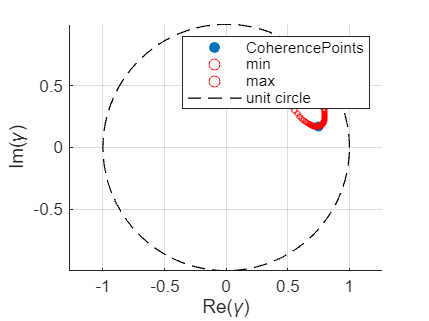


boundary_N = 60;
boundary_vals = BoundaryScan(fileName, boundary_N);

figure('Name','Coherence points','NumberTitle','off');
hold on;  % keep all plots in the same figure
axis equal; grid on;

% scatter plot of your samples
scatter(real(gamma), imag(gamma), 30, 'filled');

scatter(real(boundary_vals(:,1)), imag(boundary_vals(:,1)),8 ,'ro', 'red');
scatter(real(boundary_vals(:,2)), imag(boundary_vals(:,2)),8 ,'ro', 'red');

% draw unit circle for reference
th = linspace(0,2*pi,500);
plot(cos(th), sin(th), 'k--', 'LineWidth', 0.7);

% labels and title
xlabel('Re(\gamma)'); 
ylabel('Im(\gamma)');


% legend
legend('CoherencePoints','min','max', 'unit circle');

hold off;  % optional, release hold